
[a, b] = CircleSpec(6);
disp(['Perimeter: ', num2str(a)]);

Perimeter: 37.6991


disp(['Area: ', num2str(b)]);

Area: 113.0973


A = [1,2 ; 3,4]; 
B = [5,6;7,8];
A.*B % matrix multiplication elementwise

ans =      5    12
    21    32


A*B % matrix multiplication

ans =     19    22
    43    50


A.' % Transpose 

ans =      1     3
     2     4


inv(B) % Matrix inverse 

ans =    -4.0000    3.0000
    3.5000   -2.5000


det(B) % determinant calculation

ans = -2.0000

FindPrimes(30)

ans =      2     3     5     7    11    13    17    19    23    29


samp = [0,1,10];
[mean_val, median_val, var] = mmv(samp)

mean_val = 3.6667

median_val = 1

var = 30.3333

syms x y
f = (3/5)*x^2 + (5/3)*y^3;

val = subs(f, [x, y], [1, 2]);
disp(['Value at (1,2) = ', char(val)])

Value at (1,2) = 209/15



% Partial derivatives
fx = diff(f, x, 1);
fyy = diff(f, y, 2);

disp(['df/dx = ', char(fx)])

df/dx = (6*x)/5


disp(['d^2f/dy^2 = ', char(fyy)])

d^2f/dy^2 = 10*y


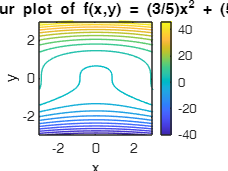


%% 2D plot - Contour plot to visualize curves like circle plotting

% Define numerical function from symbolic
f_numeric = matlabFunction(f, 'Vars', [x y]);

% Grid for plotting
[x_grid, y_grid] = meshgrid(linspace(-3,3,100), linspace(-3,3,100));
z_grid = f_numeric(x_grid, y_grid);

% Contour plot (like level curves)
figure;
contour(x_grid, y_grid, z_grid, 20); % 20 contour lines
colorbar
title('2D Contour plot of f(x,y) = (3/5)x^2 + (5/3)y^3')
xlabel('x')
ylabel('y')
axis equal

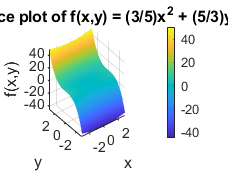


%% 3D plot - surface plot

figure;
surf(x_grid, y_grid, z_grid)
title('3D Surface plot of f(x,y) = (3/5)x^2 + (5/3)y^3')
xlabel('x')
ylabel('y')
zlabel('f(x,y)')
shading interp
colorbar

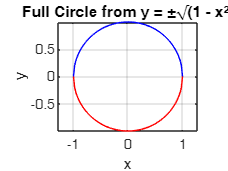

x = linspace(-1, 1, 100);
y1 = sqrt(1 - x.^2);     % upper semicircle
y2 = -sqrt(1 - x.^2);    % lower semicircle

plot(x, y1, 'b', x, y2, 'r')
axis equal
grid on
xlabel('x')
ylabel('y')
title('Full Circle from y = ±√(1 - x²)')

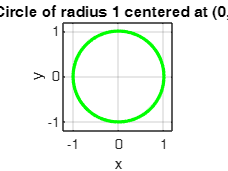

theta = linspace(0, 2*pi, 200);  % angle from 0 to 2π
x = cos(theta);  % x = cos(θ)
y = sin(theta);  % y = sin(θ)

plot(x, y, 'g', 'LineWidth', 2)
axis equal
grid on
xlabel('x')
ylabel('y')
title('Circle of radius 1 centered at (0,0)')
xlim([-1.2, 1.2])   % set x-axis limits
ylim([-1.2, 1.2])   % set y-axis limits

function [Perem, Area] = CircleSpec(radius)
    Perem = 2 * pi * radius;
    Area = pi * radius^2;
end


function [primes] = FindPrimes(h)
    primes = [];
    for k = 2 : h
        flag = true;
        for g= 2:sqrt(k)
            if mod(k,g) == 0 
                flag = false;
                break
            end
        end
        if flag 
        primes = [primes, k];
        end
    end
end

function [mean_value, median_value, variance_value] = mmv(arr)
    n = length(arr);
    mean_value = sum(arr)/n;

    sorted = sort(arr); 
    if mod(n, 2) == 1
        median_value = sorted((n + 1)/2);   
    else
        median_value = (sorted(n/2) + sorted(n/2 + 1)) / 2; 
    end

    variance_value = sum((arr - mean_value).^2) / (n - 1);   

end